# 딥러닝 신경망 아키텍처 만들기

다음 속성을 사용하여 딥러닝 신경망의 계층을 만드는 스크립트:

스크립트를 실행하여 작업 공간 변수 `lgraph`에 계층을 만듭니다.

자세한 내용은 [심층 신경망 디자이너에서 MATLAB 코드 생성](matlab:helpview('deeplearning','generate_matlab_code'))을(를) 참조하십시오.

MATLAB에서 2022-07-19 05:47:23에 자동 생성됨

## 계층 그래프 생성

신경망의 계층을 담을 계층 그래프 변수를 만듭니다.

lgraph = layerGraph();

## 계층 분기 추가

계층 그래프에 신경망의 분기를 추가합니다. 각 분기는 계층으로 구성된 선형 배열입니다.

tempLayers = [
    imageInputLayer([1 512 1],"Name","imageinput")
    convolution2dLayer([2 31],32,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","bn_conv1_1","Epsilon",0.001)
    reluLayer("Name","activation_1_relu_1")
    convolution2dLayer([2 15],48,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","bn_conv1_2","Epsilon",0.001)
    reluLayer("Name","activation_1_relu_2")
    convolution2dLayer([2 7],64,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","bn_conv1_3","Epsilon",0.001)
    reluLayer("Name","activation_1_relu_3")
    convolution2dLayer([2 1],64,"Name","conv_42","Padding","same")
    batchNormalizationLayer("Name","bn_conv1_4","Epsilon",0.001)
    reluLayer("Name","activation_1_relu_4")
    maxPooling2dLayer([1 3],"Name","max_pooling2d_1","Padding","same","Stride",[2 2])
    convolution2dLayer([1 1],64,"Name","res2a_branch2a_1","BiasLearnRateFactor",0,"Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_1","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_1")
    convolution2dLayer([3 3],64,"Name","res2a_branch2b_1","BiasLearnRateFactor",0,"Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_1","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_1")
    convolution2dLayer([1 1],128,"Name","conv_4","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_1","Epsilon",0.001)
    additionLayer(2,"Name","add_1")
    reluLayer("Name","activation_4_relu_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],64,"Name","res2a_branch2a_2","BiasLearnRateFactor",0,"Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_2","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_2")
    convolution2dLayer([3 3],64,"Name","res2a_branch2b_2","BiasLearnRateFactor",0,"Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_2","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_2")
    convolution2dLayer([1 1],128,"Name","conv_5","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_2","Epsilon",0.001)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_2")
    reluLayer("Name","activation_4_relu_2")
    convolution2dLayer([1 1],128,"Name","conv_13","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_3","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_3")
    convolution2dLayer([3 3],128,"Name","conv_14","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_3","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_3")
    convolution2dLayer([1 1],256,"Name","conv_6","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_3","Epsilon",0.001)
    additionLayer(2,"Name","add_3")
    reluLayer("Name","activation_4_relu_3")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","conv_15","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_4","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_4")
    convolution2dLayer([3 3],128,"Name","conv_16","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_4","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_4")
    convolution2dLayer([1 1],256,"Name","conv_7","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_4","Epsilon",0.001)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_4")
    reluLayer("Name","activation_4_relu_4")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","conv_18","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_5","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_5")
    convolution2dLayer([3 3],128,"Name","conv_17","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_5","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_5")
    convolution2dLayer([1 1],256,"Name","conv_8","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_5","Epsilon",0.001)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_5")
    reluLayer("Name","activation_4_relu_5")
    convolution2dLayer([1 1],128,"Name","conv_19","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_6","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_6")
    convolution2dLayer([3 3],128,"Name","conv_20","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_6","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_6")
    convolution2dLayer([1 1],256,"Name","conv_9","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_6","Epsilon",0.001)
    additionLayer(2,"Name","add_6")
    reluLayer("Name","activation_4_relu_6")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","conv_22","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_7","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_7")
    convolution2dLayer([3 3],128,"Name","conv_21","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_7","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_7")
    convolution2dLayer([1 1],256,"Name","conv_10","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_7","Epsilon",0.001)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_7")
    reluLayer("Name","activation_4_relu_7")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],128,"Name","conv_23","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_8","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_8")
    convolution2dLayer([3 3],128,"Name","conv_24","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_8","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_8")
    convolution2dLayer([1 1],256,"Name","conv_11","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_8","Epsilon",0.001)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_8")
    reluLayer("Name","activation_4_relu_8")
    convolution2dLayer([1 1],256,"Name","conv_26","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_9","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_9")
    convolution2dLayer([3 3],256,"Name","conv_25","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_9","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_9")
    convolution2dLayer([1 1],512,"Name","conv_12","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_9","Epsilon",0.001)
    additionLayer(2,"Name","add_9")
    reluLayer("Name","activation_4_relu_9")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","conv_29","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_10","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_10")
    convolution2dLayer([3 3],256,"Name","conv_28","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_10","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_10")
    convolution2dLayer([1 1],512,"Name","conv_27","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_10","Epsilon",0.001)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_10")
    reluLayer("Name","activation_4_relu_10")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","conv_32","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_11","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_11")
    convolution2dLayer([3 3],256,"Name","conv_31","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_11","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_11")
    convolution2dLayer([1 1],512,"Name","conv_30","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_11","Epsilon",0.001)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_11")
    reluLayer("Name","activation_4_relu_11")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],256,"Name","conv_35","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_12","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_12")
    convolution2dLayer([3 3],256,"Name","conv_34","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_12","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_12")
    convolution2dLayer([1 1],512,"Name","conv_33","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_12","Epsilon",0.001)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_12")
    reluLayer("Name","activation_4_relu_12")
    convolution2dLayer([1 1],512,"Name","conv_38","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_13","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_13")
    convolution2dLayer([3 3],512,"Name","conv_37","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_13","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_13")
    convolution2dLayer([1 1],1024,"Name","conv_36","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_13","Epsilon",0.001)
    additionLayer(2,"Name","add_13")
    reluLayer("Name","activation_4_relu_13")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([1 1],512,"Name","conv_41","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2a_14","Epsilon",0.001)
    reluLayer("Name","activation_2_relu_14")
    convolution2dLayer([3 3],512,"Name","conv_40","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2b_14","Epsilon",0.001)
    reluLayer("Name","activation_3_relu_14")
    convolution2dLayer([1 1],1024,"Name","conv_39","Padding","same")
    batchNormalizationLayer("Name","bn2a_branch2c_14","Epsilon",0.001)];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","add_14")
    reluLayer("Name","activation_4_relu_14")
    averagePooling2dLayer([7 1],"Name","avgpool2d","Padding","same")
    fullyConnectedLayer(8,"Name","fc")
    softmaxLayer("Name","fc_softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% 헬퍼 변수 정리
clear tempLayers;

## 계층 분기 연결

신경망의 모든 분기를 연결하여 신경망의 그래프를 만듭니다.

lgraph = connectLayers(lgraph,"activation_4_relu_1","res2a_branch2a_2");
lgraph = connectLayers(lgraph,"activation_4_relu_1","add_2/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2c_2","add_2/in1");
lgraph = connectLayers(lgraph,"activation_4_relu_3","conv_15");
lgraph = connectLayers(lgraph,"activation_4_relu_3","add_4/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2c_4","add_4/in1");
lgraph = connectLayers(lgraph,"activation_4_relu_4","conv_18");
lgraph = connectLayers(lgraph,"activation_4_relu_4","add_5/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2c_5","add_5/in1");
lgraph = connectLayers(lgraph,"activation_4_relu_6","conv_22");
lgraph = connectLayers(lgraph,"activation_4_relu_6","add_7/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2c_7","add_7/in1");
lgraph = connectLayers(lgraph,"activation_4_relu_7","conv_23");
lgraph = connectLayers(lgraph,"activation_4_relu_7","add_8/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2c_8","add_8/in1");
lgraph = connectLayers(lgraph,"activation_4_relu_9","conv_29");
lgraph = connectLayers(lgraph,"activation_4_relu_9","add_10/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2c_10","add_10/in1");
lgraph = connectLayers(lgraph,"activation_4_relu_10","conv_32");
lgraph = connectLayers(lgraph,"activation_4_relu_10","add_11/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2c_11","add_11/in1");
lgraph = connectLayers(lgraph,"activation_4_relu_11","conv_35");
lgraph = connectLayers(lgraph,"activation_4_relu_11","add_12/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2c_12","add_12/in1");
lgraph = connectLayers(lgraph,"activation_4_relu_13","conv_41");
lgraph = connectLayers(lgraph,"activation_4_relu_13","add_14/in2");
lgraph = connectLayers(lgraph,"bn2a_branch2c_14","add_14/in1")

lgraph =   LayerGraph - 속성 있음:

         Layers: [158×1 nnet.cnn.layer.Layer]
    Connections: [166×2 table]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


## 계층 플로팅

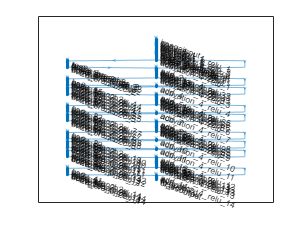

plot(lgraph);